# **Actividad Regresión Lineal y Polinomial**

Diego Alejandro Espejo López A01638341

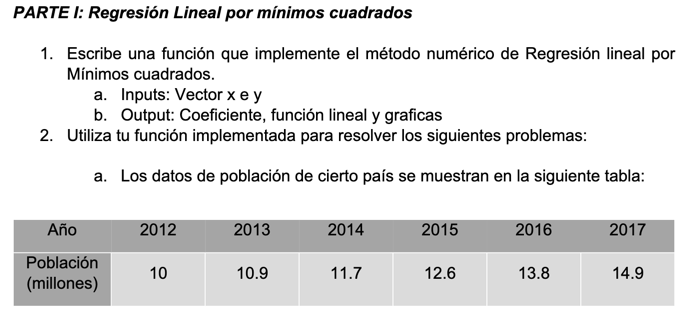

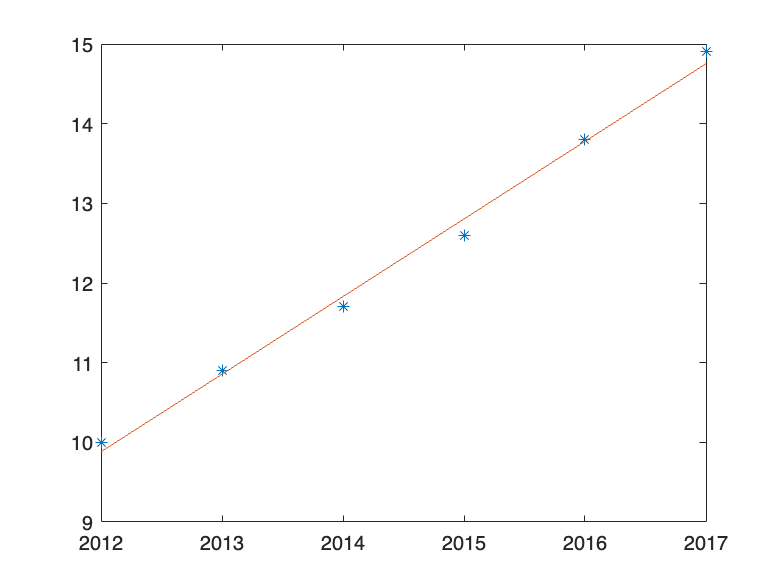

f(x) = 0.974286x + (-1950.381905)

r2 = 0.9942

x = [2012 2013 2014 2015 2016 2017];
y = [10 10.9 11.7 12.6 13.8 14.9];

r2 = min_cuad(x,y)

function r2 = min_cuad(x,y)
    n = numel(x);
    
    a = ((n*sum(x.*y)) - (sum(x)*sum(y))) / ((n*sum(x.^2) - sum(x)^2));
    b = (sum(y) - a*sum(x)) / (n);
    
    xP = sum(x) / numel(x);
    yP = sum(y) / numel(y);
    
    r = (sum((x-xP).*(y-yP))) / (sqrt(sum((x-xP).^2)) * sqrt(sum((y-yP).^2)));
    r2 = r^2;
    
    yy = a.*x + b;
    plot(x,y,'*',x,yy);
    fprintf("f(x) = %fx + (%f)", a,b);
end

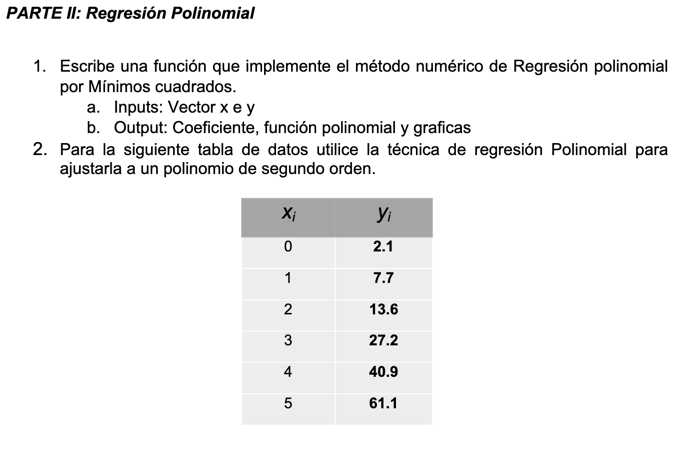

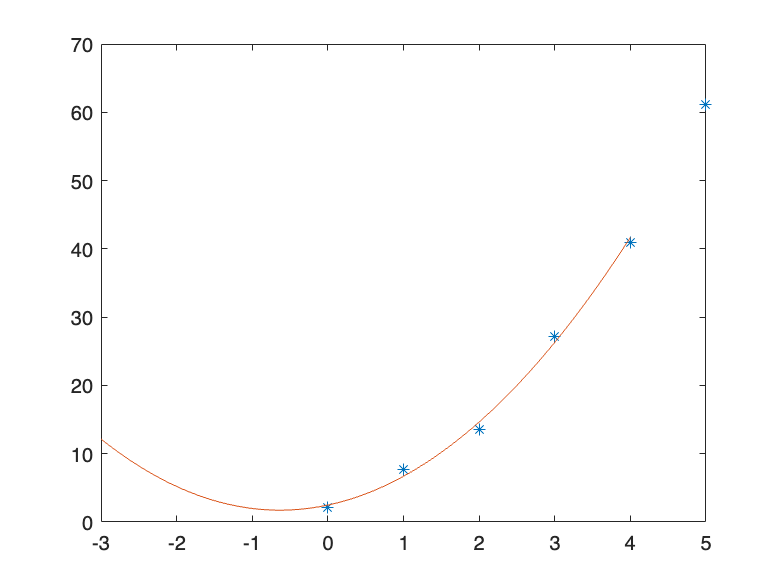

f(x) = 1.860714x^2 + 2.359286x + 2.478571

r2 = 0.9471

x = [0 1 2 3 4 5];
y = [2.1 7.7 13.6 27.2 40.9 61.1];

r2 = reg_poli(x,y)

function r2 = reg_poli(x,y)
    a = zeros(3,3);
    b = zeros(3,1);

    X4 = sum(x.^4);
    X3 = sum(x.^3);
    X2 = sum(x.^2);
    X = sum(x);

    a(1,1) = X4;
    a(1,2) = X3;
    a(1,3) = X2;

    a(2,1) = X3;
    a(2,2) = X2;
    a(2,3) = X;

    a(3,1) = X2;
    a(3,2) = X;
    a(3,3) = numel(y);

    b(1,1) = sum((x.^2).*y);
    b(2,1) = sum(x.*y);
    b(3,1) = sum(y);

    coeff = a\b; % Me da los resultados de a b c
    plot(x,y, "*")
    
    xP = sum(x) / numel(x);
    yP = sum(y) / numel(y);
    r = (sum((x-xP).*(y-yP))) / (sqrt(sum((x-xP).^2)) * sqrt(sum((y-yP).^2)));
    r2 = r^2;
    
    x = [-3:.1:4];
    y = coeff(1,1)*x.^2 + coeff(2,1)*x + coeff(3,1);
    hold on
    plot(x,y)

    fprintf("f(x) = %fx^2 + %fx + %f", coeff(1,1), coeff(2,1), coeff(3,1))
end